# Final Project

clear all;
clf;
syms s k EPS;

## Motor Parameters

terminal_resistance = 8.75;     % (R)
terminal_inductance = 0.535;    % (L)
torque_constant = 28.0;         % (Km|Kt)
speed_constant = 342;           % (1/Kb|Ks)
torque_gradient = 107;
rotor_inertia  = 5.44;          % (J)

R = terminal_resistance         % Resistance (ohm)

R = 8.7500

L = terminal_inductance*10^-3   % Inductance (H)

L = 5.3500e-04

Km = torque_constant*10^-3      % Motor Constant

Km = 0.0280

Kb = 1/(speed_constant*2*pi/60) % Back EMF Constant

Kb = 0.0279

J = rotor_inertia/100^2/1000    % Torque ()

J = 5.4400e-07

#### No Load Friction

   
$$b=\;\;\frac{I_{\textrm{no}\;\textrm{load}} *K_m }{\omega_{\textrm{no}\;\textrm{load}} }=\frac{35\ldotp 4\textrm{mA}*8\ldotp 53\textrm{mNm}}{1382\ldotp 301\frac{\textrm{rad}}{s}}$$


I_no_load = 12.8*10^-3;
w_no_load = 6110*2*pi/60;
b = I_no_load*Km/w_no_load % no load friction constant

b = 5.6014e-07

## System Transfer Function

#### Driver

data = readmatrix('Transient_Response.csv');
driver = tfest(data,2)

driver =
 
  From input "u1" to output "y1":
     0.7588 s + 0.02799
  ------------------------
  s^2 + 0.6965 s + 0.02429
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                   
Estimated using TFEST on time domain data.
Fit to estimation data: 91.68%            
FPE: 0.615, MSE: 0.6146                   


[driver_num driver_den] = tfdata(driver, 'v');

#### Open Loop

elec_dyn = tf(1,[L R]);
mech_dyn = tf(1,[J b]);
motor = tf(feedback(Km*series(elec_dyn, mech_dyn), Kb));
integrator = tf(1, [1 0]);

open_loop = tf(series(driver,series(motor,integrator)))

open_loop =
 
  From input "u1" to output:
                           0.02125 s + 0.0007838
  ------------------------------------------------------------------------
  2.91e-10 s^5 + 4.761e-06 s^4 + 0.00079 s^3 + 0.0005481 s^2 + 1.911e-05 s
 
Continuous-time transfer function.




rlocus(open_loop)                   % Completes feedback path for us
[Gm,Pm,Wcg,Wcp] = margin(open_loop) % Completes feedback path for us

Gm = 4.0525

Pm = 5.4736

Wcg = 10.4409

Wcp = 5.1733

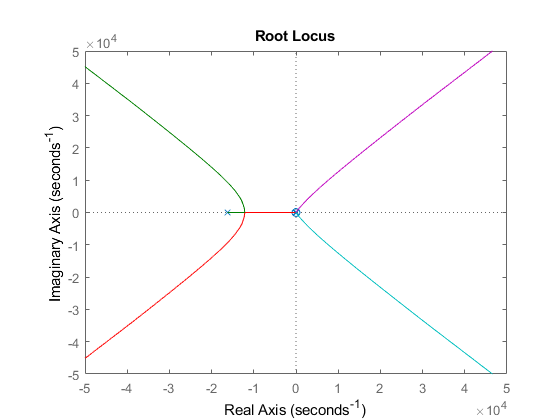

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


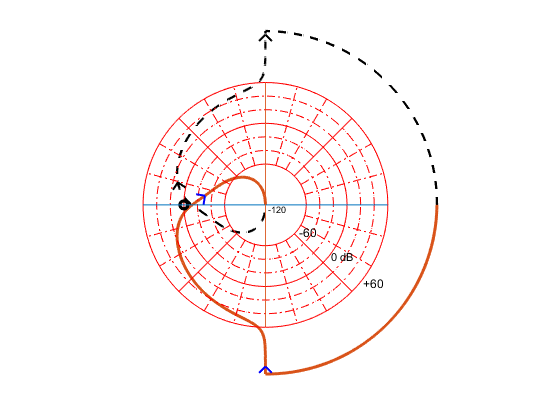

nyqlog(open_loop)                         % Must have nyqlog.m saved in same folder



Kp = Gm*0.5                         % Kp = 50%(Ku)

Kp = 2.0263

#### Closed Loop

sys = feedback(Kp*open_loop,1) % sensor not yet included but feedback path must be 1 anyways

sys =
 
  From input "u1" to output:
                                0.04305 s + 0.001588
  ---------------------------------------------------------------------------------
  2.91e-10 s^5 + 4.761e-06 s^4 + 0.00079 s^3 + 0.0005481 s^2 + 0.04307 s + 0.001588
 
Continuous-time transfer function.



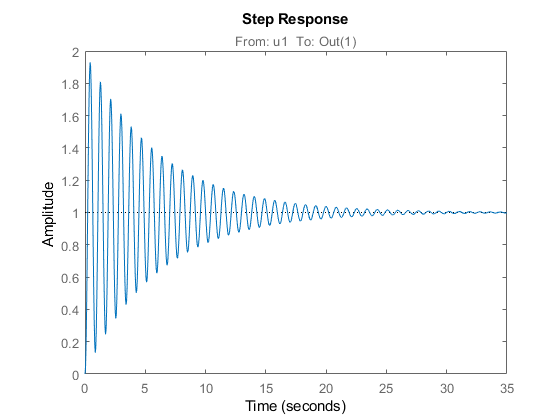

step(sys)

## PID Setup

P = 0.5  % Pole introduced for derivative term

P = 0.5000

K = Kp;

[x1,y1] = pol2cart(pi/4, P/2)

x1 = 0.1768

y1 = 0.1768

[x2,y2] = pol2cart(-pi/4, P/2)

x2 = 0.1768

y2 = -0.1768


Z1 = x1 + j*y1

Z1 = 0.1768 + 0.1768i

Z2 = x2 + j*y2

Z2 = 0.1768 - 0.1768i


Ki = K*Z1*Z2/P;
Kp = (K*(Z1+Z2)-Ki)/P;
Kd = (K-Kp)/P;

controller = tf(parallel(parallel(tf(Kp), series(tf(Ki), tf(1,[1 0]))), series(tf(Kd), tf([P 0], [1 P]))))

controller =
 
  2.026 s^2 + 0.7164 s + 0.1266
  -----------------------------
           s^2 + 0.5 s
 
Continuous-time transfer function.



pid_sys =
 
                                 0.04305 s^3 + 0.01681 s^2 + 0.003252 s + 9.926e-05
  -----------------------------------------------------------------------------------------------------------------
  2.91e-10 s^7 + 4.761e-06 s^6 + 0.0007924 s^5 + 0.0009431 s^4 + 0.04334 s^3 + 0.01682 s^2 + 0.003252 s + 9.926e-05
 
Continuous-time transfer function.



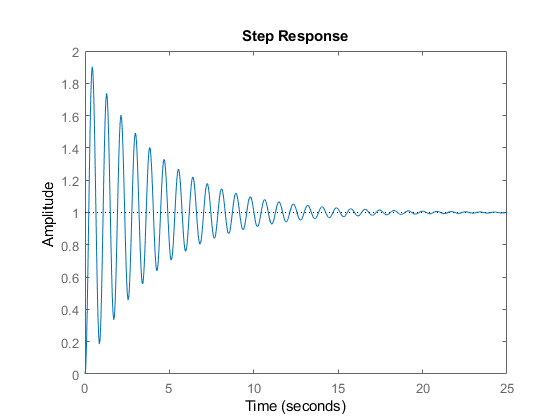


pid_sys = feedback(series(controller,series(driver,series(motor,integrator))), 1)